Jack Martin

Colorado School of Mines

SEED Lab

Assignment 2, Tuning

2/5/2024

motor:

clc;

%% variables %%
K = 1.6; % DC gain (rad/Vs)
sigma = 12; % time constant reciprocal (1/s)

%% test %%
tps = [0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 625.00, 625.00, 750.00, 767.86, 803.57, 821.43, 803.57, 821.43, 803.57, 803.57, 821.43, 821.43, 821.43, 785.71, 821.43, 821.43, 803.57, 821.43, 821.43, 803.57, 821.43, 821.43, 803.57, 803.57, 821.43, 803.57, 821.43, 821.43, 803.57, 803.57, 821.43, 821.43, 803.57, 821.43, 821.43];
volt = [0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00, 3.00];
tps = tps * (pi / 1600)

tps =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    1.2272    1.2272    1.4726    1.5077    1.5778    1.6129    1.5778    1.6129    1.5778    1.5778    1.6129    1.6129    1.6129    1.5427    1.6129    1.6129    1.5778    1.6129    1.6129    1.5778    1.6129    1.6129    1.5778    1.5778    1.6129    1.5778    1.6129    1.6129    1.5778    1.5778    1.6129


volt = volt / 3

volt =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


t = linspace(0, 3, 54)

t =          0    0.0566    0.1132    0.1698    0.2264    0.2830    0.3396    0.3962    0.4528    0.5094    0.5660    0.6226    0.6792    0.7358    0.7925    0.8491    0.9057    0.9623    1.0189    1.0755    1.1321    1.1887    1.2453    1.3019    1.3585    1.4151    1.4717    1.5283    1.5849    1.6415    1.6981    1.7547    1.8113    1.8679    1.9245    1.9811    2.0377    2.0943    2.1509    2.2075    2.2642    2.3208    2.3774    2.4340    2.4906    2.5472    2.6038    2.6604    2.7170    2.7736



%% simulation %%
open_system('motor') % open simulink system
out = sim('motor') % run simulation

out =   Simulink.SimulationOutput:

               Velocity: [1x1 timeseries] 
                Voltage: [1x1 timeseries] 
                   tout: [54x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


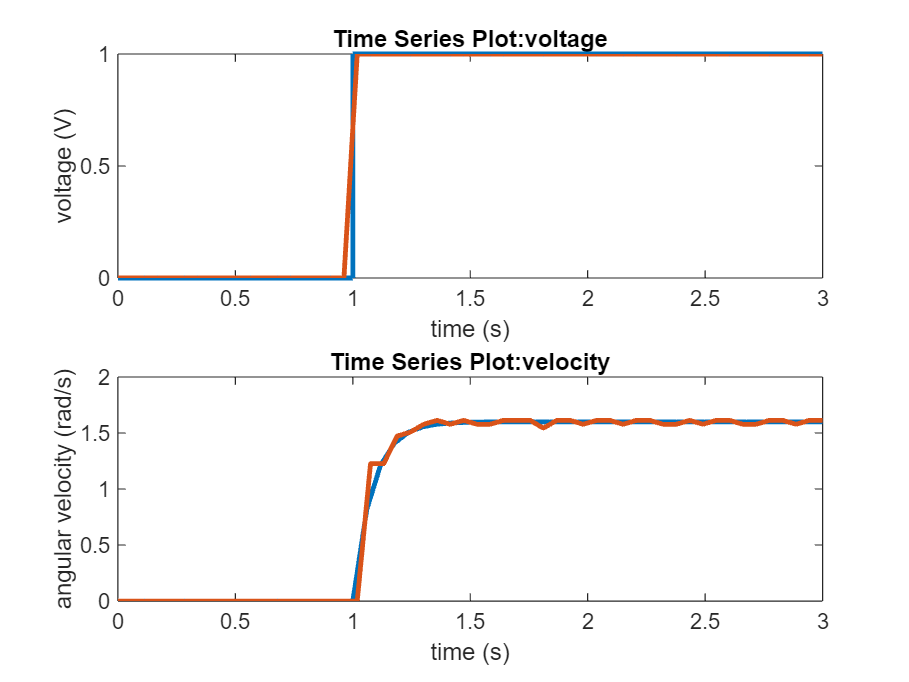


%% results %%
figure
subplot(2,1,1)
plot(out.Voltage, 'linewidth', 2)
hold on
plot(t, volt, 'linewidth', 2)
xlabel('time (s)')
ylabel('voltage (V)')
subplot(2,1,2)
plot(out.Velocity, 'linewidth', 2)
hold on
plot(t, tps, 'linewidth', 2)
xlabel('time (s)')
ylabel('angular velocity (rad/s)')

velocity control system:

clc;

%% variables %%
Kp = 10; % proportial
K = 1.6; % DC gain (rad/Vs)
sigma = 12; % time constant reciprocal (1/s)

%% test %%
time = [0, 21, 42, 63, 84, 105, 126, 147, 168, 189, 210, 231, 252, 273, 294, 315, 336, 357, 378, 399, 420, 441, 462, 483, 504, 525, 546, 567, 588, 609, 630, 651, 672, 693, 714, 735, 756, 777, 798, 819, 840, 861, 882, 903, 924, 945, 966, 987, 1008, 1029, 1050, 1071, 1092, 1113, 1135, 1156, 1177, 1198, 1220, 1241, 1263, 1284, 1305, 1326, 1348, 1369, 1391, 1412, 1433, 1454, 1476, 1497, 1519, 1540, 1561, 1582, 1604, 1625, 1647, 1668, 1689, 1710, 1732, 1753, 1775, 1796, 1817, 1838, 1860, 1881, 1903, 1924, 1945, 1966, 1988, 2009, 2031, 2052, 2073, 2094, 2116, 2137, 2159, 2180, 2201, 2222, 2244, 2265, 2287, 2308, 2329, 2350, 2372, 2393, 2415, 2436, 2457, 2478, 2500, 2521, 2543, 2564, 2585, 2606, 2628, 2649, 2671, 2692, 2713, 2734, 2756, 2777, 2799, 2820, 2841, 2862, 2884, 2905, 2927, 2948, 2969, 2990]

time =            0          21          42          63          84         105         126         147         168         189         210         231         252         273         294         315         336         357         378         399         420         441         462         483         504         525         546         567         588         609         630         651         672         693         714         735         756         777         798         819         840         861         882         903         924         945         966         987        1008        1029


time = (time / 1000)

time =          0    0.0210    0.0420    0.0630    0.0840    0.1050    0.1260    0.1470    0.1680    0.1890    0.2100    0.2310    0.2520    0.2730    0.2940    0.3150    0.3360    0.3570    0.3780    0.3990    0.4200    0.4410    0.4620    0.4830    0.5040    0.5250    0.5460    0.5670    0.5880    0.6090    0.6300    0.6510    0.6720    0.6930    0.7140    0.7350    0.7560    0.7770    0.7980    0.8190    0.8400    0.8610    0.8820    0.9030    0.9240    0.9450    0.9660    0.9870    1.0080    1.0290


actualvoltage = [-0.02, -0.02, -0.02, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, 7.8, 1.99, 0.97, 1.23, 0.75, 1.07, 1.02, 0.92, 1.09, 1.53, 1.13, 0.74, 0.96, 1.1, 0.65, 0.67, 0.59, 1.22, 1.11, 1.16, 1.34, 1.28, 1.09, 1.04, 0.99, 1.06, 1.46, 1.01, 1.19, 1.04, 1.12, 1.06, 0.7, 0.48, 0.95, 1.09, 1.22, 1.32, 1.36, 1.17, 1.09, 0.97, 0.86, 1.05, 1.05, 1.19, 0.94, 0.79, 0.96, 1.11, 0.58, 1.19, 1.33, 1.11, 0.6, 0.81, 1.29, 1.05, 0.66, 1, 1.06, 1.04, 1.33, 0.95, 0.9, 0.86, 1.21, 1.01, 1.41, 1.4, 1.47, 0.74, 0.73, 1.18, 1.12, 0.63, 0.69, 0.94, 1.07, 1.06, 0.82, 0.78, 0.89, 1.13, 1.05, 1.38, 1.42, 1.5, 1.16, 0.81, 0.94, 1.06, 0.69, 0.7]

actualvoltage =    -0.0200   -0.0200   -0.0200   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100   -0.0100    7.8000    1.9900


actualvelocity = [0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0.75, 0.88, 0.85, 0.91, 0.87, 0.87, 0.88, 0.86, 0.81, 0.86, 0.91, 0.88, 0.86, 0.92, 0.92, 0.93, 0.85, 0.86, 0.86, 0.83, 0.84, 0.86, 0.87, 0.88, 0.87, 0.82, 0.87, 0.85, 0.87, 0.86, 0.87, 0.91, 0.94, 0.88, 0.86, 0.85, 0.83, 0.83, 0.85, 0.86, 0.88, 0.89, 0.87, 0.87, 0.85, 0.88, 0.9, 0.88, 0.86, 0.93, 0.85, 0.83, 0.86, 0.92, 0.9, 0.84, 0.87, 0.92, 0.87, 0.87, 0.87, 0.83, 0.88, 0.89, 0.89, 0.85, 0.87, 0.82, 0.83, 0.82, 0.91, 0.91, 0.85, 0.86, 0.92, 0.91, 0.88, 0.87, 0.87, 0.9, 0.9, 0.89, 0.86, 0.87, 0.83, 0.82, 0.81, 0.86, 0.9, 0.88, 0.87, 0.91, 0.91]

actualvelocity =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.7500



%% simulation %%
open_system('vctrlsystem') % open simulink system
out = sim('vctrlsystem') % run simulation

out =   Simulink.SimulationOutput:

        DesiredVelocity: [1x1 timeseries] 
               Velocity: [1x1 timeseries] 
                Voltage: [1x1 timeseries] 
                   tout: [671x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


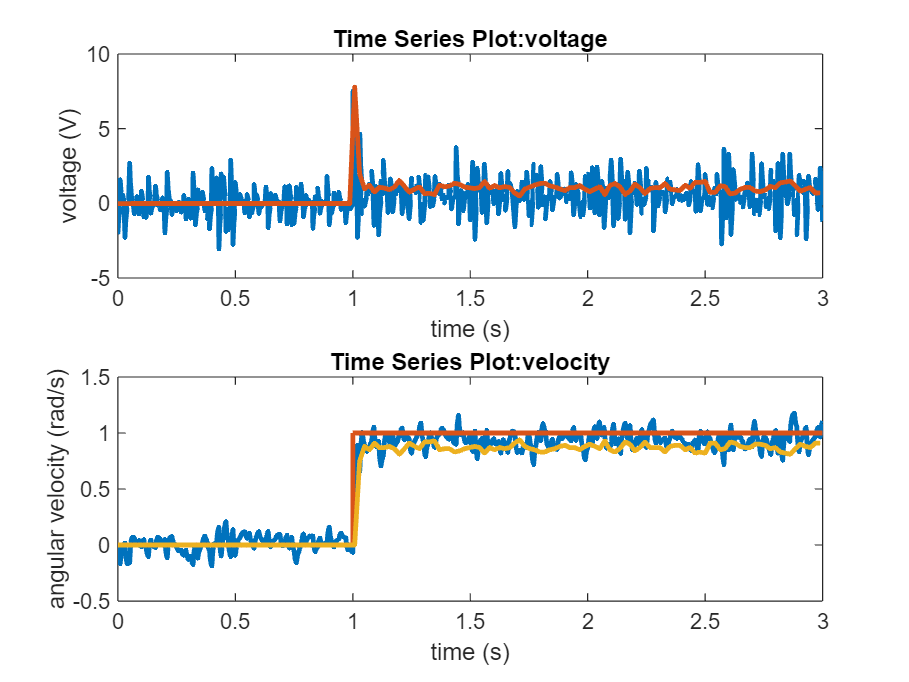


%% results %%
figure
subplot(2,1,1)
plot(out.Voltage, 'linewidth', 2)
hold on
plot(time, actualvoltage, 'linewidth', 2)
xlabel('time (s)')
ylabel('voltage (V)')
subplot(2,1,2)
plot(out.Velocity, 'linewidth', 2)
hold on
plot(out.DesiredVelocity, 'linewidth', 2)
hold on
plot(time, actualvelocity, 'linewidth', 2)
xlabel('time (s)')
ylabel('angular velocity (rad/s)')

position control system:

clc;

%% variables %%
sigma = 12; % time constant reciprocal (1/s)
K = 1.6; % DC gain (rad/Vs)
Kp = 3; % proportial gain
Ki = 0.32; % integral gain

%% test %%
%time = [0, 21, 42, 63, 84, 105, 126, 147, 168, 189, 210, 231, 252, 273, 294, 315, 336, 357, 378, 399, 420, 441, 462, 483, 504, 525, 546, 567, 588, 609, 630, 651, 672, 693, 714, 735, 756, 777, 798, 819, 840, 861, 882, 903, 924, 945, 966, 987, 1008, 1029, 1050, 1071, 1092, 1113, 1135, 1156, 1177, 1198, 1220, 1241, 1263, 1284, 1305, 1326, 1348, 1369, 1391, 1412, 1433, 1454, 1476, 1497, 1519, 1540, 1561, 1582, 1604, 1625, 1647, 1668, 1689, 1710, 1732, 1753, 1775, 1796, 1817, 1838, 1860, 1881, 1903, 1924, 1945, 1966, 1988, 2009, 2031, 2052, 2073, 2094, 2116, 2137, 2159, 2180, 2201, 2222, 2244, 2265, 2287, 2308, 2329, 2350, 2372, 2393, 2415, 2436, 2457, 2478, 2500, 2521, 2543, 2564, 2585, 2606, 2628, 2649, 2671, 2692, 2713, 2734, 2756, 2777, 2799, 2820, 2841, 2862, 2884, 2905, 2927, 2948, 2969, 2990]
%time = (time / 1000)
%actualvoltage = [-0.02, -0.02, -0.02, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, -0.01, 7.8, 1.99, 0.97, 1.23, 0.75, 1.07, 1.02, 0.92, 1.09, 1.53, 1.13, 0.74, 0.96, 1.1, 0.65, 0.67, 0.59, 1.22, 1.11, 1.16, 1.34, 1.28, 1.09, 1.04, 0.99, 1.06, 1.46, 1.01, 1.19, 1.04, 1.12, 1.06, 0.7, 0.48, 0.95, 1.09, 1.22, 1.32, 1.36, 1.17, 1.09, 0.97, 0.86, 1.05, 1.05, 1.19, 0.94, 0.79, 0.96, 1.11, 0.58, 1.19, 1.33, 1.11, 0.6, 0.81, 1.29, 1.05, 0.66, 1, 1.06, 1.04, 1.33, 0.95, 0.9, 0.86, 1.21, 1.01, 1.41, 1.4, 1.47, 0.74, 0.73, 1.18, 1.12, 0.63, 0.69, 0.94, 1.07, 1.06, 0.82, 0.78, 0.89, 1.13, 1.05, 1.38, 1.42, 1.5, 1.16, 0.81, 0.94, 1.06, 0.69, 0.7]
%actualvelocity = [0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0.75, 0.88, 0.85, 0.91, 0.87, 0.87, 0.88, 0.86, 0.81, 0.86, 0.91, 0.88, 0.86, 0.92, 0.92, 0.93, 0.85, 0.86, 0.86, 0.83, 0.84, 0.86, 0.87, 0.88, 0.87, 0.82, 0.87, 0.85, 0.87, 0.86, 0.87, 0.91, 0.94, 0.88, 0.86, 0.85, 0.83, 0.83, 0.85, 0.86, 0.88, 0.89, 0.87, 0.87, 0.85, 0.88, 0.9, 0.88, 0.86, 0.93, 0.85, 0.83, 0.86, 0.92, 0.9, 0.84, 0.87, 0.92, 0.87, 0.87, 0.87, 0.83, 0.88, 0.89, 0.89, 0.85, 0.87, 0.82, 0.83, 0.82, 0.91, 0.91, 0.85, 0.86, 0.92, 0.91, 0.88, 0.87, 0.87, 0.9, 0.9, 0.89, 0.86, 0.87, 0.83, 0.82, 0.81, 0.86, 0.9, 0.88, 0.87, 0.91, 0.91]

%% simulation %%
open_system('pctrlsystem') % open simulink system
out = sim('pctrlsystem') % run simulation

out =   Simulink.SimulationOutput:

        DesiredPosition: [1x1 timeseries] 
        DesiredVelocity: [1x1 timeseries] 
               Position: [1x1 timeseries] 
               Velocity: [1x1 timeseries] 
                Voltage: [1x1 timeseries] 
                   tout: [10603x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


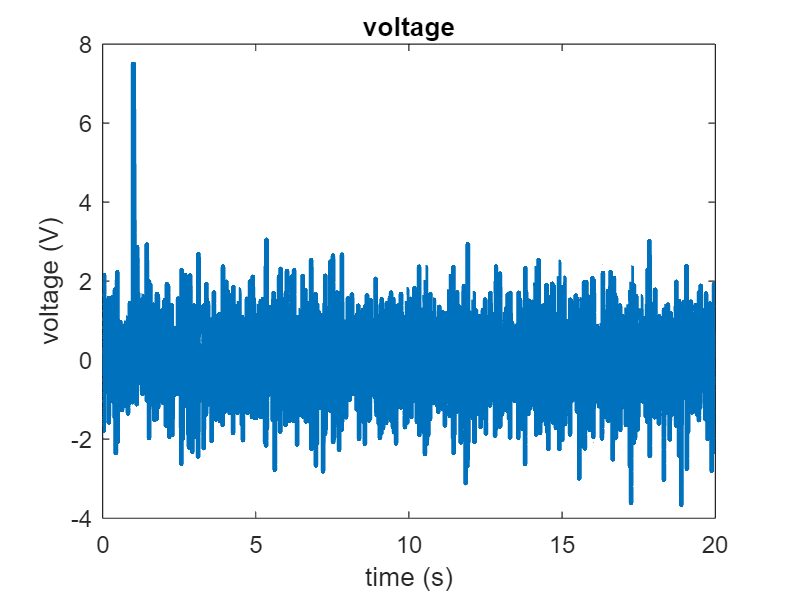


%% results %%
figure
plot(out.Voltage, 'linewidth', 2)
hold on
%plot(time, actualvoltage, 'linewidth', 2)
%xlabel('time (s)')
title('voltage')
xlabel('time (s)')
ylabel('voltage (V)')
hold off

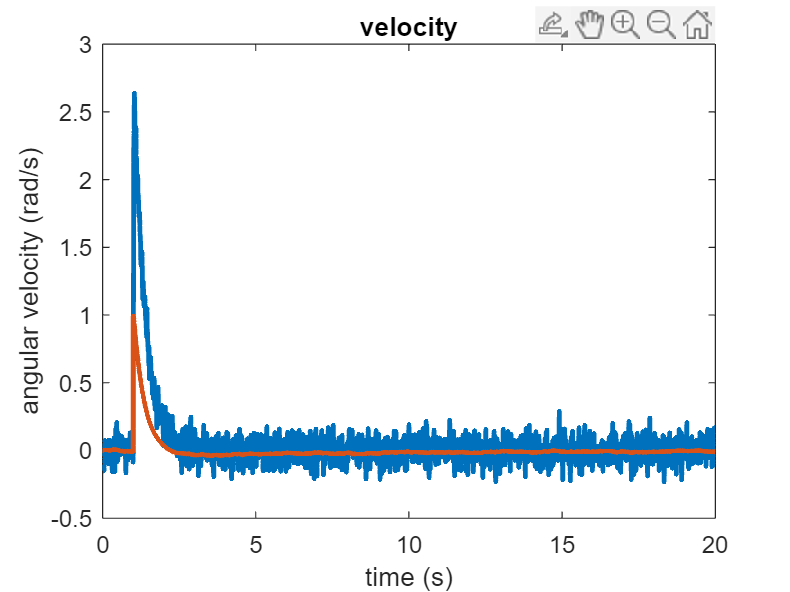


figure
plot(out.Velocity, 'linewidth', 2)
hold on
plot(out.DesiredVelocity, 'linewidth', 2)
%hold on
%plot(time, actualvelocity, 'linewidth', 2)
title('velocity')
xlabel('time (s)')
ylabel('angular velocity (rad/s)')
hold off

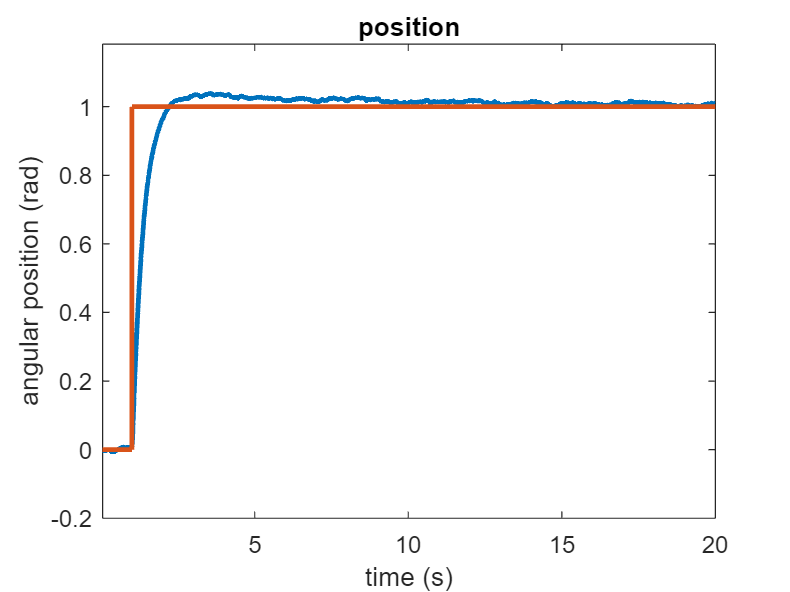


figure
plot(out.Position, 'linewidth', 2)
hold on
plot(out.DesiredPosition, 'linewidth', 2)
%hold on
%plot(time, actualposition, 'linewidth', 2)
title('position')
xlabel('time (s)')
ylabel('angular position (rad)')